## Gabriel Werpel Fernandes

## June 2024

## Load Data

% Close all figures and clear variables
clc;
close all;
clearvars;

%Process EEG Data
data = processAllEEGData();

Data for file A1_Full_Block.bdf processed successfully
Data for file A3_Full_Block.bdf processed successfully
Data for file A4_Full_Block.bdf processed successfully
Data for file A6_Alpha.bdf processed successfully
Data for file A7_Alpha.bdf processed successfully
Data for file A8_Alpha.bdf processed successfully
Data for file A9_Alpha.bdf processed successfully
Data for file C11_Alpha.bdf processed successfully
Data for file C12_Alpha.bdf processed successfully
Data for file C13_Alpha.bdf processed successfully
Data for file C14_Alpha.bdf processed successfully
Data for file C15_Alpha.bdf processed successfully
Data for file C1_Alpha.bdf processed successfully


## Plot Time-Series

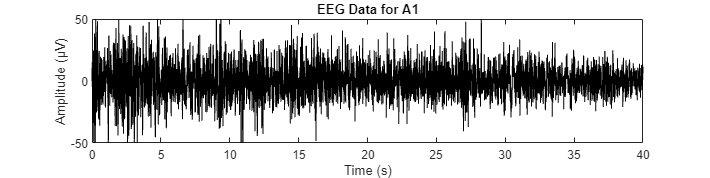

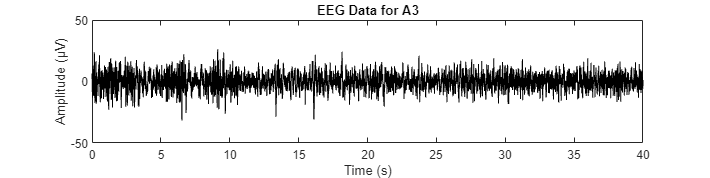

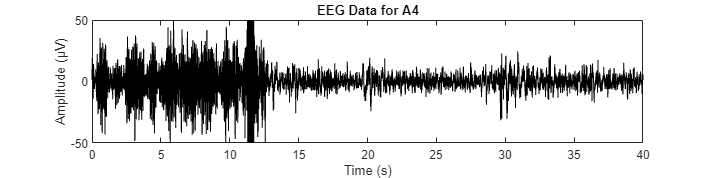

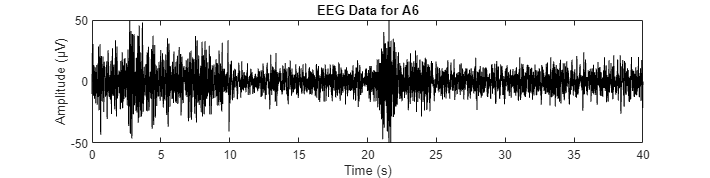

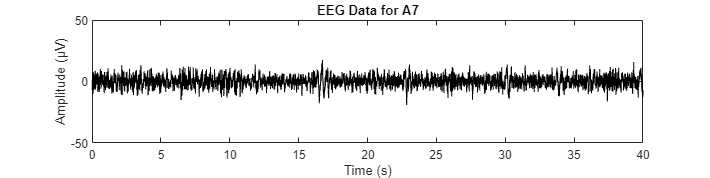

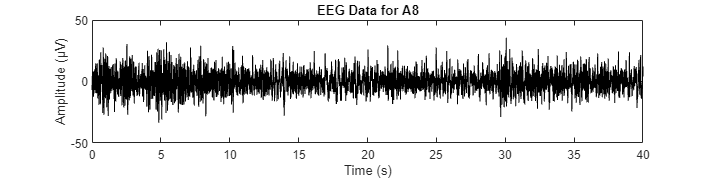

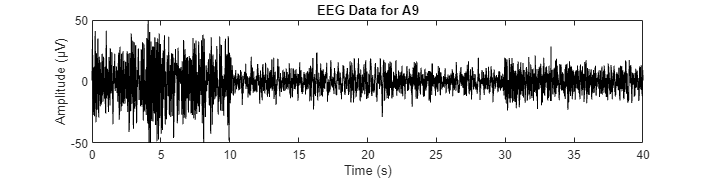

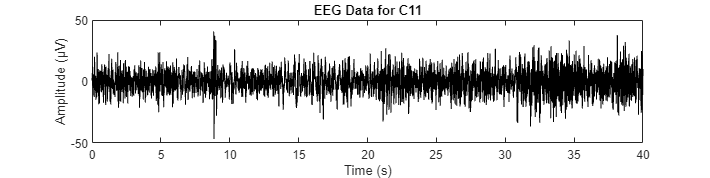

% Plot all EEG data
plotAllEEGData(data);

## Segment Data

% Segment the EEG data
segmentedData = segmentEEGDataNew(data);

## Time-Domain Analysis

### Statistical Measures: Mean, Variance, Std. Deviation, Skewness and Kurtosis

% Calculate and display the extended statistics for all keys and sections
extendedStatisticsResults = calculateExtendedStatisticsForAllSections(segmentedData);

      Key             Section             DataType      Mean      Variance    StandardDeviation    Skewness    Kurtosis
    _______    ______________________    __________    _______    ________    _________________    ________    ________

    {'A1' }    {'EC'                }    {'Normal'}     -0.158     320.02           17.889           0.012       3.441 
    {'A1' }    {'EO'                }    {'Normal'}      0.051        150           12.247          -0.039       3.837 
    {'A1' }    {'DEC'               }    {'Normal'}      -0.04      108.7           10.426           0.292       3.873 
    {'A1' }    {'NDEC'              }    {'Normal'}      0.042     78.528            8.862           0.031        3.09 
    {'A

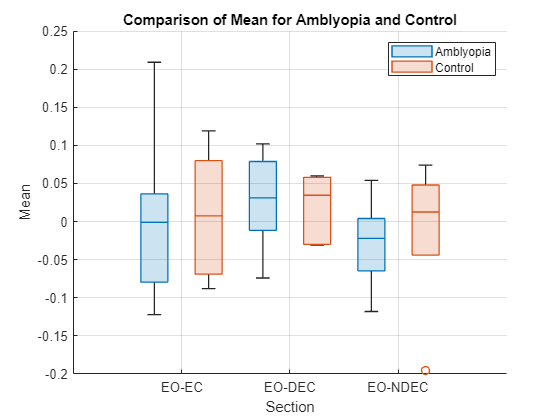

% Load the data
data = readtable('TableA.1.1.csv');

% Call the function for each metric
plotBoxChart(data, 'Mean', 'Mean');

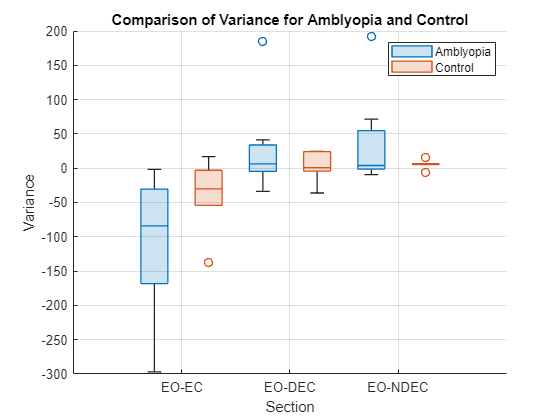

plotBoxChart(data, 'Variance', 'Variance');

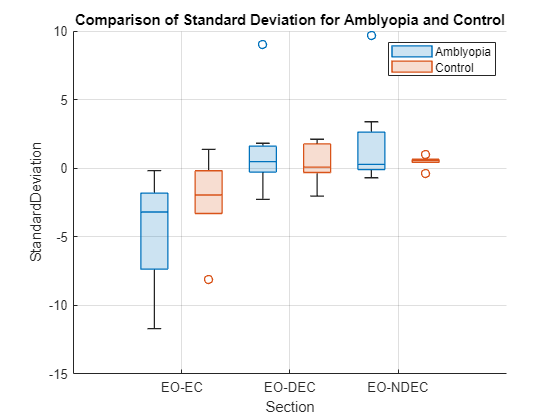

plotBoxChart(data, 'StandardDeviation', 'Standard Deviation');

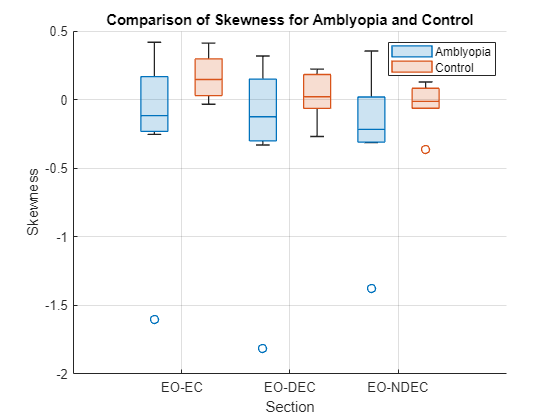

plotBoxChart(data, 'Skewness', 'Skewness');

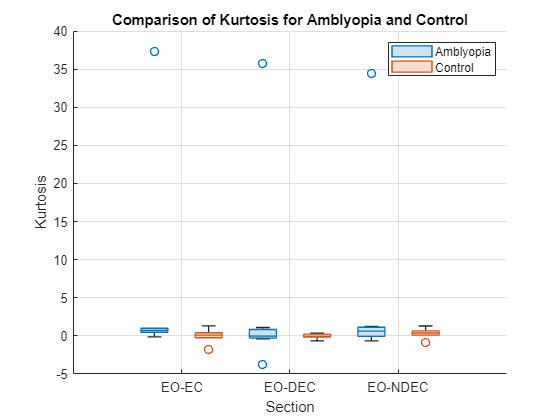

plotBoxChart(data, 'Kurtosis', 'Kurtosis');

calculateStatisticalDifferences(data, 'Mean');

Pairwise Statistical Analysis for Mean:
EO-EC vs EO-DEC: p-value = 0.3974
EO-EC vs EO-NDEC: p-value = 0.7583
EO-DEC vs EO-NDEC: p-value = 0.1008


calculateStatisticalDifferences(data, 'Variance');

Pairwise Statistical Analysis for Variance:
EO-EC vs EO-DEC: p-value = 0.0012
EO-EC vs EO-NDEC: p-value = 0.0005
EO-DEC vs EO-NDEC: p-value = 0.7976


calculateStatisticalDifferences(data, 'StandardDeviation');

Pairwise Statistical Analysis for StandardDeviation:
EO-EC vs EO-DEC: p-value = 0.0012
EO-EC vs EO-NDEC: p-value = 0.0004
EO-DEC vs EO-NDEC: p-value = 0.7700


calculateStatisticalDifferences(data, 'Skewness');

Pairwise Statistical Analysis for Skewness:
EO-EC vs EO-DEC: p-value = 0.3050
EO-EC vs EO-NDEC: p-value = 0.2184
EO-DEC vs EO-NDEC: p-value = 0.5382


calculateStatisticalDifferences(data, 'Kurtosis');

Pairwise Statistical Analysis for Kurtosis:
EO-EC vs EO-DEC: p-value = 0.8721
EO-EC vs EO-NDEC: p-value = 0.9645
EO-DEC vs EO-NDEC: p-value = 0.9025


calculateGroupStatisticalDifferences(data, 'Variance');

Group Statistical Analysis for Variance (Amblyopia vs Control):
EO-EC (Amblyopia vs Control): p-value = 0.1375
EO-DEC (Amblyopia vs Control): p-value = 0.5338
EO-NDEC (Amblyopia vs Control): p-value = 0.5338


calculateGroupStatisticalDifferences(data, 'StandardDeviation');

Group Statistical Analysis for StandardDeviation (Amblyopia vs Control):
EO-EC (Amblyopia vs Control): p-value = 0.4452
EO-DEC (Amblyopia vs Control): p-value = 0.4909
EO-NDEC (Amblyopia vs Control): p-value = 0.3912
